% =========================================================
% SMART ROOM - SIMULATION + GRAPHS + JSON EXPORT (PRO)
% =========================================================

clc; clear; close all;

settingsText = fileread('C:\Users\user\Desktop\pfe\smartroom_settings.json');
settings = jsondecode(settingsText);

T_setpoint = settings.T_setpoint;
PLIGHTING  = settings.PLIGHTING;
PDEVICE    = settings.PDEVICE;
T_EXT      = settings.T_EXT;
CO2_EXT2   = settings.CO2_EXT2;
H_EXT      = settings.H_EXT;


%% 2. SIMULATION SIMULINK
model_name = 'MODELE';
out = sim(model_name);

%% 3. EXTRACTION TIMESERIES
t = out.Tair.Time;

% ---------------- Thermique ----------------
Tair     = out.Tair.Data;
Tmur     = out.Tmur.Data;
Tairreel = out.Tairreel.Data;
Tmurreel = out.Tmurreel.Data;

% ---------------- Énergétique ----------------
CLIM      = out.CLIM.Data;
CHAUFFAGE = out.CHAUFFAGE.Data;
LIGHTING  = out.LIGHTING.Data;
DEVICES   = out.DEVICES.Data;
E_TOTAL   = out.E_TOTAL.Data;

% ---------------- Environnement ----------------
CO2 = out.CO2.Data;
Hum = out.HUM.Data;
warning = out.warning.Data;

%% 4. WARNING CONSOLE
if any(warning == 0)
    fprintf('\n✅  OK : Lampe verte — modèle conforme au réel\n\n');
else
    fprintf('\n⚠️  WARNING : Lampe rouge — modèle pas réel !\n\n');
end


✅  OK : Lampe verte — modèle conforme au réel



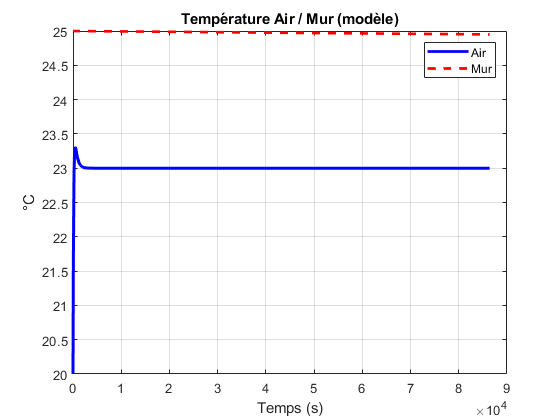

%% 4. GRAPHE : Température modèle Air / Mur
figure;
plot(t, Tair, 'b', 'LineWidth', 2); hold on;
plot(t, Tmur, 'r--', 'LineWidth', 2);
title('Température Air / Mur (modèle)');
xlabel('Temps (s)'); ylabel('°C');
legend('Air','Mur');
grid on;

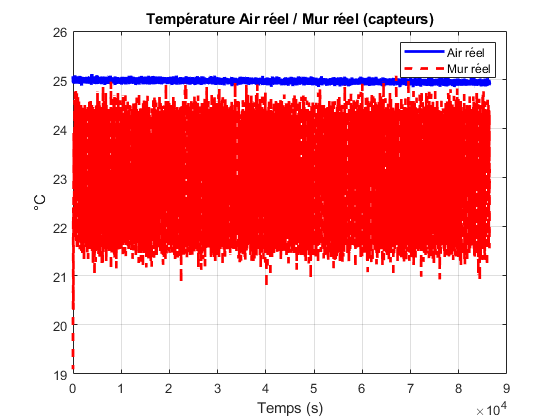


%% 5. GRAPHE : Température réelle Air / Mur
figure;
plot(t, Tairreel, 'b', 'LineWidth', 2); hold on;
plot(t, Tmurreel, 'r--', 'LineWidth', 2);
title('Température Air réel / Mur réel (capteurs)');
xlabel('Temps (s)'); ylabel('°C');
legend('Air réel','Mur réel');
grid on;

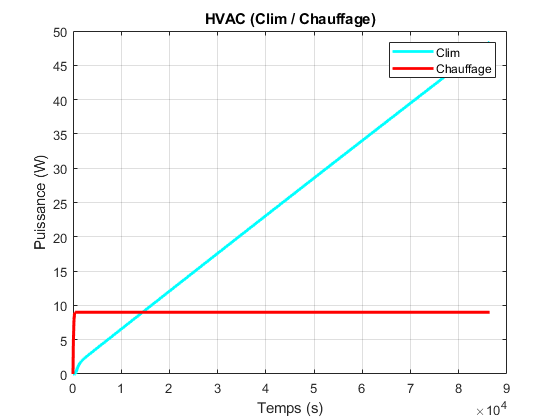


%% 7. GRAPHE : HVAC
figure;
plot(t, CLIM,      'c', 'LineWidth', 2); hold on;
plot(t, CHAUFFAGE, 'r', 'LineWidth', 2);
title('HVAC (Clim / Chauffage)');
xlabel('Temps (s)'); ylabel('Puissance (W)');
legend('Clim','Chauffage');
grid on;

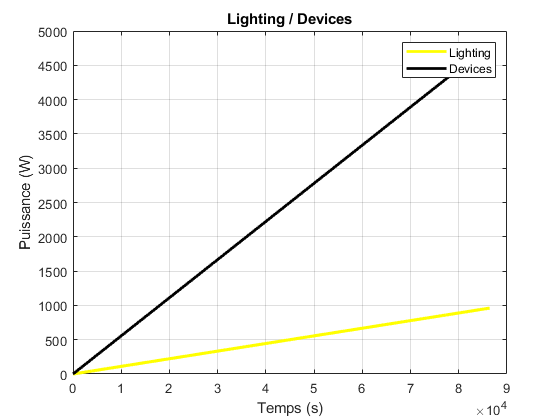


%% 8. GRAPHE : Lighting + Devices
figure;
plot(t, LIGHTING, 'y', 'LineWidth', 2); hold on;
plot(t, DEVICES,  'k', 'LineWidth', 2);
title('Lighting / Devices');
xlabel('Temps (s)'); ylabel('Puissance (W)');
legend('Lighting','Devices');
grid on;

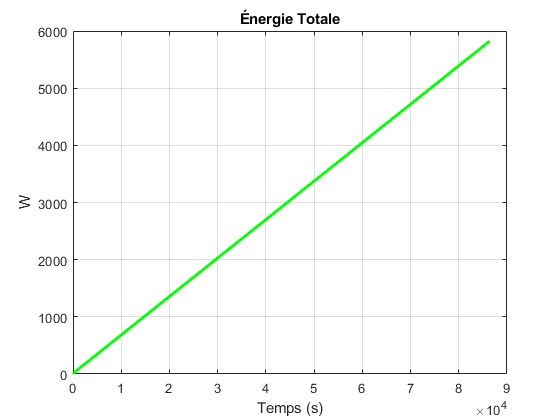


%% 9. GRAPHE : Énergie totale
figure;
plot(t, E_TOTAL, 'g', 'LineWidth', 2);
title('Énergie Totale');
xlabel('Temps (s)'); ylabel('W');
grid on;

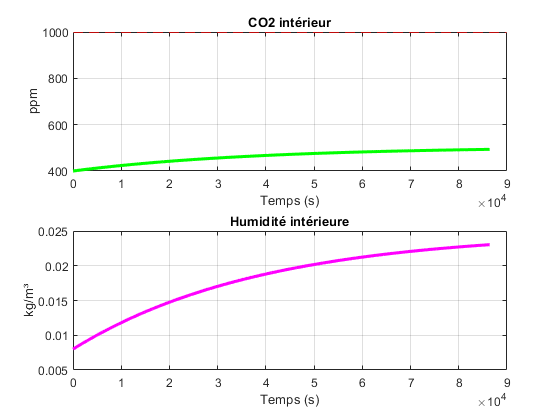


%% 10. GRAPHE : Environnement (CO2 + Humidité)
figure;

subplot(2,1,1);
plot(t, CO2, 'g', 'LineWidth', 2);
yline(1000,'r--','Seuil CO2 1000 ppm');
title('CO2 intérieur');
xlabel('Temps (s)'); ylabel('ppm');
grid on;

subplot(2,1,2);
plot(t, Hum, 'm', 'LineWidth', 2);
title('Humidité intérieure');
xlabel('Temps (s)'); ylabel('kg/m³');
grid on;


%% 11. BILAN ÉNERGIE
E_total_J   = trapz(t, E_TOTAL);
E_total_kWh = E_total_J / 3.6e6;

fprintf('\n===== BILAN ENERGIE =====\n');


===== BILAN ENERGIE =====


fprintf('Energie totale : %.4f kWh\n', E_total_kWh);

Energie totale : 69.9859 kWh


fprintf('=========================\n\n');


%% 12. STATISTIQUES ENVIRONNEMENTALES
fprintf('===== AIR QUALITY =====\n');

===== AIR QUALITY =====


fprintf('CO2 max  : %.2f ppm\n', max(CO2));

CO2 max  : 493.40 ppm


fprintf('CO2 mean : %.2f ppm\n', mean(CO2));

CO2 mean : 462.60 ppm


fprintf('Hum max  : %.4f\n',     max(Hum));

Hum max  : 0.0230


fprintf('Hum mean : %.4f\n',     mean(Hum));

Hum mean : 0.0181


fprintf('=======================\n\n');


%% DIGITAL TWIN ERROR
error_air = out.error_air.Data;
error_mur = out.error_mur.Data;

fprintf('===== DIGITAL TWIN ERROR =====\n');

===== DIGITAL TWIN ERROR =====


fprintf('Erreur Air moyenne : %.4f C\n', mean(error_air));

Erreur Air moyenne : 0.3571 C


fprintf('Erreur Air max     : %.4f C\n', max(error_air));

Erreur Air max     : 2.2354 C


fprintf('Erreur Mur moyenne : %.4f C\n', mean(error_mur));

Erreur Mur moyenne : 0.0252 C


fprintf('Erreur Mur max     : %.4f C\n', max(error_mur));

Erreur Mur max     : 0.1247 C


fprintf('==============================\n\n');

%% 14. EXPORT JSON
results.time = t;

% Thermique modèle
results.temperature_air = Tair;
results.temperature_mur = Tmur;

% Thermique réel (capteurs)
results.temperature_air_reel = Tairreel;
results.temperature_mur_reel = Tmurreel;

% Énergétique
results.clim              = CLIM;
results.chauffage         = CHAUFFAGE;
results.lighting          = LIGHTING;
results.devices           = DEVICES;
results.energy_signal     = E_TOTAL;
results.energy_total_kWh  = E_total_kWh;

% Environnement
results.co2      = CO2;
results.humidity = Hum;
results.warning  = warning;
jsonText = jsonencode(results);
  
results.error_air = out.error_air.Data;
results.error_mur = out.error_mur.Data;
output_path = 'C:\Users\user\Desktop\pfe\smartroom_results.json';
fid = fopen(output_path, 'w', 'n', 'UTF-8');

if fid == -1
    error('Impossible d ecrire le fichier JSON');
end

fprintf(fid, '%s', jsonText);
fclose(fid);

%% FIN
disp('=================================================');

disp('SMART ROOM TERMINE AVEC SUCCES');

SMART ROOM TERMINE AVEC SUCCES


disp(['JSON exporte : ', output_path]);

JSON exporte : C:\Users\user\Desktop\pfe\smartroom_results.json


disp('=================================================');